syms m [1 7]; %masses of elements
syms I [1 7]; %moments of inertia
syms f1 f2 f3 f4 f5 f6 f7 [3,1]; %forces applied to frame from element
syms s1 s2 s3 s4 s5 s6 s7 s7End [3,1]; %position of each element
syms v1 v2 v3 v4 v5 v6 v7 [3,1]; %position of each element
syms a1 a2 a3 a4 a5 a6 a7 [3,1]; %position of each element
syms t1 t2 t3 t4 t5 t6 t7 ot7 [3,1]; %angle of each element
syms tv1 tv2 tv3 tv4 tv5 tv6 tv7 [3,1];
syms ta1 ta2 ta3 ta4 ta5 ta6 ta7 [3,1];
syms w1 w2 w3 w4 w5 w6 w7 [3,1]; %weight of each element
syms gf1 gf2 gf3 gf4 gf5 gf6 gf7 [3,1]; %force on outer gear acting on inner gear
syms l1 l2 l3 l4 l5 l6 l7 lcontact [3,1]; %distance from centre to element
syms r [1 7]; %radius of each element
syms gfa [1 7]; %absolute gear force on each eement


syms T_z l3_ab l5_ab Rz Rvector g2 rw l7_ab C_friction7 separation23 separation35 N_sun N_idler N_planet cost13 sint13 cost73 sint73;
syms step_start [3,1];
syms step_height step_pitch ratio7Weight ratio7Contact;
syms T [3,1];
syms F_react5 [3,1];
syms M_react5 [3,1];
syms F_react6 [3,1];
syms M_react6 [3,1];
syms F_react7 F_reactPrime7 [3,1];

f=sym([f1, f2, f3, f4, f5, f6, f7]);
gf=sym([gf1, gf2, gf3, gf4, gf5, gf6, gf7]);
s=sym([s1, s2, s3, s4, s5, s6, s7]);
v=sym([v1, v2, v3, v4, v5, v6, v7]);
a=sym([a1, a2, a3, a4, a5, a6, a7]);
t=sym([t1, t2, t3, t4, t5, t6, t7]);
tv=sym([tv1, tv2, tv3, tv4, tv5, tv6, tv7]);
ta=sym([ta1, ta2, ta3, ta4, ta5, ta6, ta7]);
l=sym([l1, l2, l3, l4, l5, l6, l7]);
w=sym([w1, w2, w3, w4, w5, w6, w7]);

g= [0, -g2, 0].';
g=sym(g);

P = sym(pi)
%t = [zeros(1,7); zeros(1,7); t_z]
%tv = [zeros(1,7); zeros(1,7); tv_z]
%ta = [zeros(1,7); zeros(1,7); ta_z]

T = [0; 0; T_z];

testeqs = [w1==m1*g; m1*a1==w1; m1==1; g2==9.81]
%solve(testeqs)

eqns_force= unwrap_y([ ...
    m1*a1 == f2+f3+f4+f5+f6+f7+w1; ...
    m2*a2 == w2-f2+gf3+gf4; ...
    m3*a3 == w3-f3-gf3+gf5; ...
    m4*a4 == w4-f4-gf4+gf6; ...
    m5*a5 == w5-f5-gf5+F_react5; ...
    m6*a6 == w6-f6-gf6+F_react6; ...
    m7*a7==-f7+F_react7+w7 ...
    ])
eqns_weight = unwrap_y(w==m.*g)
eqns_accelleration = unwrap_y(m1*a1==w1)
assignmnent_masses = unwrap_y(m == 1)
assignmnent_g = unwrap_y(g2 == 9.81)
testeqs=[eqns_weight; eqns_accelleration; assignmnent_g; assignmnent_masses]
%solve(testeqs)
assignment_gearForce = unwrap_y(gf == 0)
assignment_reaction = unwrap_y([F_react53 == 0, F_react63 == 0, F_react73 == 0])
assignment_accelleration = unwrap_y(a == 0)
testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; assignment_gearForce; assignment_accelleration;]
%solve(testeqs)

symbols = symvar(testeqs)
symnames = string(symbols)

Rvector2 = [sin(t13); cos(t13); 0];
eqns_gearForce = unwrap_y([gf1==0, gf2==0, gf3==gfa3*Rvector2, gf4==gfa4*Rvector2, gf5==gfa5*Rvector2, gf6==gfa6*Rvector2, gf7 == 0]);
assignment_gearForceAbsolute = unwrap_y(gfa == 0)
assignment_angle = unwrap_y([t(:,1:6) == 0, t(:,7)==[0; 0; P] ])
% testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; eqns_gearForce; assignment_accelleration; assignment_angle; assignment_gearForceAbsolute;]
%solve(testeqs)

moment1=I1*-ta1 == cross(l3,f3) + cross(l4,f4) + cross(l5,f5) + cross(l6,f6);
moment7=I7*-ta7 == T + cross(l7*ratio7Weight, w7) + cross(l7*ratio7Contact, F_react7)


assignment_inertias= unwrap_y(I == 1)
assignment_forces= unwrap_y(f13 == 0)
assignment_angularAccelleration = unwrap_y(ta == 0)
assignment_lengths = unwrap_y([l(1,:) == 1;l(2:3,:) == 0])
assignment_radius = unwrap_y(r == 1)
assignment_torque = T_z == 0
assignment_momentReaction = [M_react63 == 0]
eqns_tailGroundFriction = [F_react71 ==  -C_friction7*F_react72];
% testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; eqns_gearForce; assignment_accelleration; assignment_angle; eqns_moments; assignment_inertias;assignment_angularAccelleration;assignment_lengths;assignment_radius;assignment_momentReaction;
%     F_react73 == 0; F_react6 == 0; F_react71 == 0
%     T_z == 1];
% solve(testeqs)



eqns_moments = unwrap_y([
    I1*-ta1 == cross(l3,f3) + cross(l4,f4) + cross(l5,f5) + cross(l6,f6);
    I2*ta23 == T_z - r2*gfa3 + r2*gfa4;
    I3*ta33 == -r3 * gfa3 - r3* gfa5;
    I4*ta43 == r4 * gfa4 + r4* gfa6;
    I5*ta53 == -r5 * gfa5 + M_react53;
    I6*ta63 == r6 * gfa6 + M_react63;
    I7*-ta7 == T + cross(l7/2, w7) + cross(l7, F_react7)
    ])

eqns_accelleration = [a1 == a2;
    a2 == a5 + cross(-l5, ta1) + cross(cross(tv1,-l5),tv1);
    a3 == a2 + cross(l3, ta1) + cross(cross(tv1,l3),tv1);
    a4 == a2 + cross(l4, ta1) + cross(cross(tv1,l4),tv1);
    a5 == a2 + cross(l5, ta1) + cross(cross(tv1,l5),tv1);
    a6 == a2 + cross(l6, ta1) + cross(cross(tv1,l6),tv1);
    a7==  a1 + cross(l7/2, ta7)]

assignment_angularVelocity = unwrap_y(tv == 0)
eqns_angularAcelleration = [ta3-ta1 == -r2/r3*(ta2-ta1);
    ta4-ta1 == -r2/r3*(ta2-ta1);
    ta5-ta1 == -r3/r5*(ta3-ta1);
    ta6-ta1 == -r3/r5*(ta4-ta1);
    ]

assignment_radius = [r2==0.070*50/(50+33)
    r3==0.041*33/(16+33)
    r4==r3
    r5==0.041*16/(16+33)
    r6==r5]

assignment_lengths = [l(1,1) == 0;
    l(1,2)==0; 
    l(1,3)==0.07;
    l(1,4)==-0.07;
    l(1,5)==0.041;
    l(1,6)==-0.041;
    l(1,7)==-0.425;
    unwrap_y(l(2:3,:) == 0)]


% testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; eqns_gearForce; eqns_moments; assignment_inertias; assignment_lengths;assignment_radius;
%     eqns_accelleration; eqns_angularAcelleration; eqns_tailGroundFriction;
%     assignment_angularVelocity; assignment_angle;
%     F_react73 == 0; F_react6 == 0; M_react6==0; a5==0; ta5==0; C_friction7 == 0.1;
%     T_z == 0];
%sol=solve(testeqs)
%sol.C_friction7
%vpa(sol.F_react52)

condition_2d = [unwrap_y(a(3,:) == 0);
    unwrap_y(v(3,:) == 0);
    unwrap_y(s(3,:) == 0);
    unwrap_y(ta(1:2,:) == 0);
    unwrap_y(tv(1:2,:) == 0);
    unwrap_y(t(1:2,:) == 0);
    ]

% testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; eqns_gearForce; eqns_moments; assignment_inertias; assignment_lengths;assignment_radius;
%     eqns_accelleration; eqns_angularAcelleration; eqns_tailGroundFriction;
%     condition_2d;
%     assignment_angularVelocity; assignment_angle;
%     F_react73 == 0; F_react6 == 0; M_react6==0; a5==0; ta5==0; C_friction7 == 0.1;
%     T_z == 0];


%[test, eqs] = mysolver(testeqs)


%[test, tteqs] = mysolver(eqs)

eqns_angularAcelleration = [ta3-ta1 == -r2/r3*(ta2-ta1);
    ta4-ta1 == -r2/r3*(ta2-ta1);
    ta5-ta1 == -r3/r5*(ta3-ta1);
    ta6-ta1 == -r3/r5*(ta4-ta1);
    
    ]

Rvector = [cos(t13); -sin(t13); 0];
Rvector2 = [sin(t13); cos(t13); 0];
Rvector7 = [cos(t73); -sin(ot73); 0];
eqns_lengths = [l1==0;
    l2==0;
    l3==l3_ab*Rvector;
    l4==-l3_ab*Rvector;
    l5==l5_ab*Rvector;
    l6==-l5_ab*Rvector;
    l7==l7_ab*Rvector7;
    t73 == pi-ot73
    separation23 == l3_ab;
    separation35==l5_ab-l3_ab;
    ]
eqns_radius = [r2==separation23*N_sun/(N_sun+N_idler)
    r3==separation35*N_idler/(N_planet+N_idler)
    r4==r3
    r5==separation35*N_planet/(N_planet+N_idler)
    r6==r5]

% testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; eqns_gearForce; eqns_moments; assignment_inertias; eqns_lengths;eqns_radius;
%     eqns_accelleration; eqns_angularAcelleration; eqns_tailGroundFriction;
%     condition_2d;
%     assignment_angularVelocity; assignment_angle;
%     separation35 == 0.041; separation23 == 0.07; rw == 0.075; l7_ab == 0.425;
%     N_idler == 33; N_sun == 50; N_planet == 16; C_friction7 == 0.1;
%     F_react73 == 0; F_react6 == 0; M_react6==0; a5==0; ta5==0; unwrap_y(v == 0);
%     T_z == 0; t13 == 0; t73 == P];

%[sol, unsolved] = mysolver(testeqs)
%sol
%t13=0
%t73=P
%testeqs= subs(testeqs, [sint13, cost13], [sin(t13), cos(t13)])
%testeqs= subs(testeqs, [sint73, cost73], [sin(t73), cos(t73)])
%sol=solve(testeqs)
%vpa(sol.ta13)


assignment_angle = [unwrap_y(t(:,1:6) == 0); t(1:2,7)==0]

eqns_displacement = [s1 == s2;
    s2 == s5 + -l5;
    s3 == s2 + l3;
    s4 == s2 + l4;
    s5 == s2 + l5;
    s6 == s2 + l6;
    s7 == s2 + l7/2;
    s7End == s2 + l7;
    ];
condition_tailOnGround = [s7End2 == 0; ratio7Contact == 1; eqns_tailGroundFriction;
    ta73 == ((l7_ab^2 - l72^2)*a22 + l72*v22^2)/(l7_ab^3 * (1 - l72^2/l7_ab^2)^(3/2)); %d^2/dt^2 (arcsin(l72(t)/l7_ab))
    ]

% testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; eqns_gearForce; eqns_moments; assignment_inertias; eqns_lengths;eqns_radius;
%     eqns_accelleration; eqns_angularAcelleration; eqns_displacement;
%     condition_2d; condition_tailOnGround;
%     assignment_angularVelocity; assignment_angle; unwrap_y(v == 0);
%     separation35 == 0.041; separation23 == 0.07; rw == 0.075; l7_ab == 0.425;
%     N_idler == 33; N_sun == 50; N_planet == 16; C_friction7 == 0.1;
%     s5 == [0;rw;0];
%     F_react73 == 0; F_react6 == 0; M_react6==0; a5==0; ta5==0;
%     step_start == [rw; 0; 0]; step_height == 0.15; step_pitch == 0.2;
%     T_z == 0];
%[sol, unsolved] = mysolver(testeqs)




assignmnent_masses = [m7 == 0.43095538069190569841;
    m2 == 2*0.056167152496905625725;
    m1 == 2*0.13271340229034475633;
    m3 == 2*0.018874380082186052732;
    m4 == m3;
    m5 == 2*0.05463272607293223615;
    m6 == m5;
    ratio7Weight == 0.25;
    ]
assignment_inertias = [I2 == 2*3.437592086857546033e-05;
    I5 == 2*6.116925860141665791e-05;
    I6 == I5;
    I1 == 2*0.00076846598232952812758;
    I3 == 2*6.6879087944629165118e-06;
    I4 == I3;
    I7 == 3279.681e-6; %From onshape
    ]




%Lifting against step from ground, calculate stall torque
testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; eqns_gearForce; eqns_moments; assignment_inertias; eqns_lengths;eqns_radius;
    eqns_accelleration; eqns_angularAcelleration; eqns_displacement;
    condition_2d; condition_tailOnGround;
    assignment_angularVelocity; assignment_angle; unwrap_y(v == 0);
    s5 == [0;rw;0]; a5==0; ta5==0;
    separation35 == 0.041; separation23 == 0.07; rw == 0.075; l7_ab == 0.425;
    N_idler == 33; N_sun == 50; N_planet == 16; C_friction7 == 0.0;
    F_react73 == 0; F_react6 == 0; M_react6==0; 
    step_start == [rw; 0; 0]; step_height == 0.15; step_pitch == 0.2;
    unwrap_y(a == 0)
    ];
% [sol, unsolved] = mysolver(testeqs)



assignment_angle=unwrap_y([t13 == 0.00, t53 == 0, t(3,[2:4,6])==0])
%rolling on ground, back wheel lifting
testeqs=[eqns_weight; eqns_force; assignmnent_g; assignmnent_masses; eqns_gearForce; eqns_moments; assignment_inertias; eqns_lengths;eqns_radius;
    eqns_accelleration; eqns_angularAcelleration;  eqns_displacement;
    condition_2d; condition_tailOnGround;
    assignment_angularVelocity; assignment_angle; unwrap_y(v == 0);
    s5 == [2*rw;step_height+rw;0];
    separation35 == 0.041; separation23 == 0.07; rw == 0.075; l7_ab == 0.425;
    N_idler == 33; N_sun == 50; N_planet == 16; C_friction7 == 0.0;
    F_react73 == 0; F_react6 == 0; M_react6==0; 
    step_start == [rw; 0; 0]; step_height == 0.15; step_pitch == 0.2;
    a51 == ta53*rw; a52 == 0; M_react53 == - F_react51 * rw;
    T_z ==3
    ]; 
% [sol, unsolved] = mysolver(testeqs)


%rolling on step, back wheel lifting, tail on step

Rmatrix7 = [
    cos(ot73), -sin(ot73), 0;
    sin(ot73), cos(ot73), 0;
    0, 0, 1
    ];


condition_tailOnStep = [
    ot73 == atan((s12-step_height)/(s11-step_start1));
    ratio7Contact == (step_height-s12)/l72;
    ta73 == (((v12)/(step_start(1) + s11) - ((step_height + s12) * v11)/(step_start(1) + s11)^2) * ((2 * (step_height + s12) * v12)/(step_start(1) + s11)^2 - (2 * (step_height + s12)^2 * v11)/(step_start(1) + s11)^3))/((step_height + s12)^2/(step_start(1) + s11)^2 + 1)^2 - (-((step_height + s12) * v11)/(step_start(1) + s11)^2 + (2 * (step_height + s12) * v11^2)/(step_start(1) + s11)^3 - (2 * v11 * v12)/(step_start(1) + s11)^2 + (a12)/(step_start(1) + s11))/((step_height + s12)^2/(step_start(1) + s11)^2 + 1) %d^2/dt^2(180 - tan^(-1)((s12(t) + step_height)/(s11(t) + step_start)))
    F_reactPrime71 == - F_reactPrime72 * C_friction7
    F_react7 == Rmatrix7 * F_reactPrime7 
    ]
assignment_v = unwrap_y([ ...
    v(1,:) == 1; ...
    v(2,:) == 0])
eqns_velocity = [
    v1 == v2;
    v2 == v5 + cross(-l5, tv1);
    v3 == v2 + cross(l3, tv1);
    v4 == v2 + cross(l4, tv1);
    v5 == v2 + cross(l5, tv1);
    v6 == v2 + cross(l6, tv1);
    ];
eqns_angularVelocity = [
    tv3-tv1 == -r2/r3*(tv2-tv1);
    tv4-tv1 == -r2/r3*(tv2-tv1);
    tv5-tv1 == -r3/r5*(tv3-tv1);
    tv6-tv1 == -r3/r5*(tv4-tv1);
    ];
condition_rolling = [
    a51 == ta53*rw; 
    a52 == 0; 
    M_react53 == - F_react51 * rw;
    v51 == tv53*rw;
    v52 == 0;
    s51 == t53*rw;
    ]

eqns_angle = [t3-t1 == -r2/r3*(t2-t1);
    t4-t1 == -r2/r3*(t2-t1);
    t5-t1 == -r3/r5*(t3-t1);
    t6-t1 == -r3/r5*(t4-t1);
    ];
condition_wheel2NoContact = [F_react73 == 0; F_react6 == 0; M_react6==0;]
assignment_gears = [separation35 == 0.041; separation23 == 0.07; rw == 0.075; l7_ab == 0.425;
    N_idler == 33; N_sun == 50; N_planet == 16; C_friction7 == 0.0;]
assignment_steps = [step_start == [rw; 0; 0]; step_height == 0.15; step_pitch == 0.2;]

% testeqs=[eqns_weight; eqns_force;  eqns_gearForce; eqns_moments;  eqns_lengths;eqns_radius;
%     eqns_accelleration; eqns_angularAcelleration; eqns_displacement; eqns_velocity; eqns_angularVelocity; 
%     assignmnent_g; assignmnent_masses; assignment_inertias; assignment_gears; assignment_steps; 
%     condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact;
%     assignment_angle; 
%     s5 == [2*rw+step_pitch;step_height*2+rw;0];
%     tv13 == 0; tv23 == 0;
%     T_z ==3
%     ]; 
% [sol, unsolved] = mysolver(testeqs)

testeqs=[eqns_weight; eqns_force;  eqns_gearForce; eqns_moments;  eqns_lengths; eqns_radius;
    eqns_accelleration; eqns_velocity; eqns_displacement; 
    eqns_angularAcelleration; eqns_angularVelocity; eqns_angle;
    assignmnent_g; assignmnent_masses; assignment_inertias; assignment_gears; assignment_steps; 
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact;
    s52 == step_height*2+rw
    T_z ==3
    ]; 
[sol, unsolved] = mysolver(testeqs, 0)

testeqs=[unsolved;
    t13 == 0; s51 == 1.5*step_pitch; 
    tv13 == 0; tv23 == 0;
    ]; 

[sol2, unsolved2] = mysolver(testeqs, 1, sol)

framesol = []


framesol =

     []



frameeqs = unsolved

Step_Value = 0.005;
t_beg = 0;
t_end = 1;
t_intial=0;
u_intial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;




for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i); %t13
    up2=u(2,i); %t23
    up3=u(3,i); %tv13
    up4=u(4,i); %tv23
    framesol = [framesol; mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4;], 1)];
    k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], 1);
    k2 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], 1);
    k3 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], 1);
    k4 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
    i
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

f = fieldnames(sol)

f = 165×1 cell array
    {'C_friction7'   }
    {'F_react53'     }
    {'F_react61'     }
    {'F_react62'     }
    {'F_react63'     }
    {'F_react73'     }
    {'F_reactPrime71'}
    {'F_reactPrime73'}
    {'I1'            }
    {'I2'            }
    {'I3'            }
    {'I4'            }
    {'I5'            }
    {'I6'            }
    {'I7'            }
    {'M_react61'     }
    {'M_react62'     }
    {'M_react63'     }
    {'N_idler'       }
    {'N_planet'      }
    {'N_sun'         }
    {'T_z'           }
    {'a13'           }
    {'a23'           }
    {'a33'           }
    {'a43'           }
    {'a52'           }
    {'a53'           }
    {'a63'           }
    {'a73'           }


nframes = length(framesol)

nframes = 44

for i = 1:length(f)
    for j = 1:nframes
        framesol(j).(f{i}) = sol.(f{i});
    end
end

F(length(framesol)) = struct('cdata',[],'colormap',[]);
for j=1:length(framesol)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(framesol(j).s61, framesol(j).s62, framesol(j).rw);
    line([framesol(j).s61,framesol(j).s61+framesol(j).rw*cos(-framesol(j).t63+pi/4)],[framesol(j).s62,framesol(j).s62+framesol(j).rw*sin(-framesol(j).t63+pi/4)])
    
    circle(framesol(j).s51, framesol(j).s52, framesol(j).rw);
    line([framesol(j).s51,framesol(j).s51+framesol(j).rw*cos(-framesol(j).t53+pi/4)],[framesol(j).s52,framesol(j).s52+framesol(j).rw*sin(-framesol(j).t53+pi/4)])
    
    %frame
    line([framesol(j).s51,framesol(j).s61],[framesol(j).s52,framesol(j).s62])
    
    %Tail
    line([framesol(j).s11,framesol(j).s7End1],[framesol(j).s12,framesol(j).s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [framesol(j).step_start1-10; framesol(j).step_start2];
    for i= 1:5
        corner(:,2*i) =  [framesol(j).step_start1+framesol(j).step_pitch*(i-1); framesol(j).step_start2+framesol(j).step_height*(i-1)];
        corner(:,2*i+1) =  [framesol(j).step_start1+framesol(j).step_pitch*(i-1); framesol(j).step_start2+framesol(j).step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;


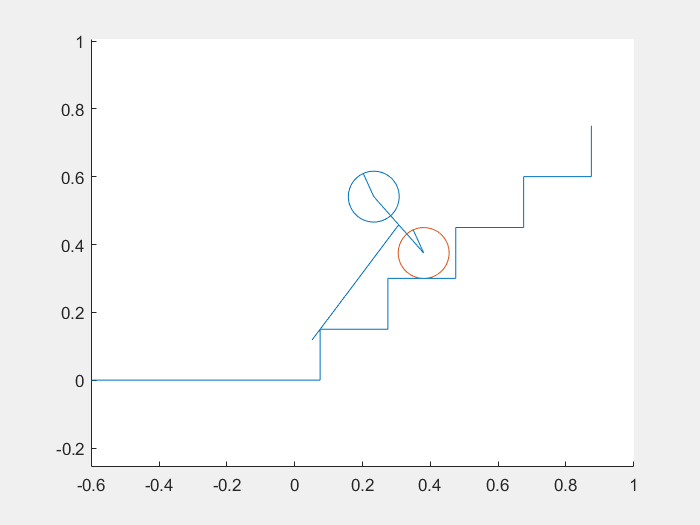


movie(fig, F, 1, 1/h);



f=figure('visible','on');
hold on;
%wheels
circle(sol.s61, sol.s62, sol.rw);
line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])

circle(sol.s51, sol.s52, sol.rw);
line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])

%frame
line([sol.s51,sol.s61],[sol.s52,sol.s62])

%Tail
line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])

axis equal;
xlim([-0.6,1])
%ylim([-0.1, 0.5])
%step
corner(:,1) = [sol.step_start1-10; sol.step_start2];
for i= 1:5
    corner(:,2*i) =  [sol.step_start1+sol.step_pitch*(i-1); sol.step_start2+sol.step_height*(i-1)];
    corner(:,2*i+1) =  [sol.step_start1+sol.step_pitch*(i-1); sol.step_start2+sol.step_height*(i)];
end
line(corner(1,:), corner(2,:))
% line([sol.step_start1-10, sol.step_start1], [sol.step_start2,sol.step_start2])
% line([sol.step_start1, sol.step_start1], [sol.step_start2, sol.step_start2+ sol.step_height])
% line([sol.step_start1, sol.step_start1+sol.step_pitch], [sol.step_height, sol.step_height])
hold off;



function k = solvek(x)
mysolversolve()
end

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end